# Notebook 7: Probability of False Detection Simulations

This will be a notebook that is used for the creation of the control experiments for the Monte Carlo simulations. This is going to be testing of the KCC for the probability of false detection exploration. We want the pure noise signals to reveal no peaks for correlation outputs. This will be traced for multiple different SNR values from 1 to -30. This is going to be a primary focus in the results section.

Each SNR value will have 5-10 trials of the correlation value for the signals. They will be repeated and then recorded.

## Developing signals

% --Setup
    clear; clc; format compact; close all; 
    cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Pure white noise data
    white_data = randi(100, 1, length(ref_signal))./ 0.64;
    white_data = white_data - mean(white_data);
    time = 0:1/fs:T;

% --Developing Brownian Noise analysis
    cn = dsp.ColoredNoise('brown', length(ref_signal));
    brownian_data = cn();
    brownian_data = brownian_data ./ 100;
    brownian_data = [brownian_data - mean(brownian_data)]';

% --Creating pink noise
    pn = pinknoise(length(ref_signal));

% --Calculate white noise power
    noise_power = sum(white_data.^2)/(2*length(white_data) + 1);
    SNR_w = 10*log10(noise_power);
    fprintf("Noise power of the white noise dataset is %3.3f dB",SNR_w)

Noise power of the white noise dataset is 30.121 dB

% --Calculate colored noise power
    noise_power = sum(brownian_data.^2)/(2*length(brownian_data) + 1);
    SNR = 10*log10(noise_power);
    fprintf("Noise power of the Brownian noise dataset is %3.3f dB", SNR)

Noise power of the Brownian noise dataset is -13.360 dB

## Detection Simulations

For these simulations, we should only get out random noise content, meaning that there is NO correlation, this can be either a random set of data, or a very low correlation with a high first value indicating a very high variance within the signal, meaning no correlated data. The spike must not occur at the beginning or the end in order for a detection event to occur. This is because that would mean that the correlation must be larger than the variance of the signal, which for detection, this must be assumed true. 

### White Noise Detection

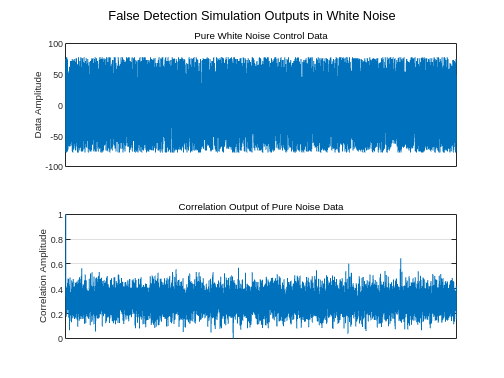

% --Call correlation
    corr_output = kxcorr(white_data, ref_signal);

% --Plot outputs
    figure()
    subplot(2,1,1)
    plot(white_data)
        ylabel('Data Amplitude')
        subtitle("Pure White Noise Control Data")
        hold on
        grid on
        xlim([0 length(white_data)])
        sgtitle("False Detection Simulation Outputs in White Noise")
        set(gca,'XTick',[])

    subplot(2,1,2)
    plot(corr_output)
        ylabel('Correlation Amplitude')
        hold on
        grid on
        subtitle("Correlation Output of Pure Noise Data")
        xlim([0 length(white_data)])
        set(gca,'XTick',[])

% --Calculating correlation coefficient
    correlation_coeff = mean(corr_output(2:end));
    fprintf("Correlation coefficient is %3.3f, SNR is %3.3f \n", correlation_coeff, SNR_w)

Correlation coefficient is 0.302, SNR is 30.121 


### Brownian Noise Detection

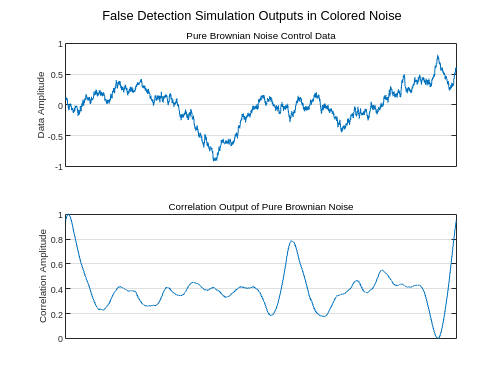

% --Call correlation algorithm
    corr_output = kxcorr(brownian_data, ref_signal);

% --Plot outputs
    figure()
    subplot(2,1,1)
    plot(brownian_data)
        ylabel('Data Amplitude')
        subtitle("Pure Brownian Noise Control Data")
        hold on
        grid on
        xlim([0 length(white_data)])
        sgtitle("False Detection Simulation Outputs in Colored Noise")
        set(gca,'XTick',[])

    subplot(2,1,2)
    plot(corr_output)
        ylabel('Correlation Amplitude')
        hold on
        grid on 
        subtitle("Correlation Output of Pure Brownian Noise")
        xlim([0 length(white_data)])
        set(gca,'XTick',[])

% --Find the correlation coefficient
    correlation_coeff = mean(corr_output(2:end));
    fprintf("Correlation coefficient is %3.3f, SNR is %3.3f \n", correlation_coeff, SNR)

Correlation coefficient is 0.395, SNR is -13.360 


## Noise Identification

This section is to identify what kind of noise is being created with our data, i.e. white noise, or colored noise.

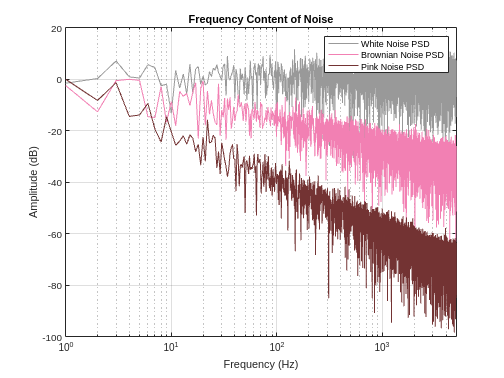

% --Taking FFT of signals
    f_data = fft(white_data);
    f_data_mag = abs(f_data);
    f_data_amp = 2 .* f_data_mag ./ (length(white_data));
    f_data_amp = f_data_amp(1:round(length(f_data_amp) / 2));
    f_data_amp = mag2db(f_data_amp);
    f_data_amp = f_data_amp - mean(f_data_amp);

    f_b_data = fft(brownian_data);
    f_b_data_mag = abs(f_b_data);
    f_b_data_amp = 2 .* f_b_data_mag ./ (length(brownian_data));
    f_b_data_amp = f_b_data_amp(1:round(length(f_b_data_amp) / 2));
    f_b_data_amp = mag2db(f_b_data_amp);
    f_b_data_amp = f_b_data_amp - max(f_b_data_amp);

    f_p_data = fft(pn);
    f_p_data_mag = abs(f_p_data);
    f_p_data_amp = 2 .* f_p_data_mag ./ (length(pn));
    f_p_data_amp = f_p_data_amp(1:round(length(f_p_data_amp) / 2));
    f_p_data_amp = mag2db(f_p_data_amp);
    f_p_data_amp = f_p_data_amp - max(f_p_data_amp);

    frequencies = (1/T).*(0:length(f_data_amp) - 1);

% --Plotting Noise
    figure();
    semilogx(frequencies, f_data_amp, "Color", [0.6 0.6 0.6]);
        hold on
        grid on
        xlabel('Frequency (Hz)')
        ylabel('Amplitude (dB)')
        xlim([0 5000])
        title('Frequency Content of Noise')
    semilogx(frequencies, f_p_data_amp, "Color", [0.95 0.5 0.7])
    semilogx(frequencies, f_b_data_amp, "Color", [0.45 0.2 0.2])
    legend("White Noise PSD", "Brownian Noise PSD", "Pink Noise PSD"); 

This would be considered white noise because the slope is 0 and the mean remains the same across the entire spectrum on a logarithmic spectrum. The brownian noise spectral density follows the correct -20dB per decade curve that we would expect it to, proving that it is in fact brownian noise content. 

## Function Definitions

### Linear Absolute Value

                
$$K(x,y) = |(x + y)|$$


function kf = Labs_kernel(x, y) % Time domain defintion of kernel

    % --Find the kernel
        kf = abs(x + y);

end

### Cubic Kernel

                
$$K(x,y) = -(x \odot y + 1)^3$$


function kf = cubic_kernel(x, y)

    % --Find kernel
        kf = (x.*y + 1).^3;

end

### RBF Kernel

                
$$K(x,y) = exp(\frac{-(x^2 + y^2)}{2\sigma})$$


function kf = rbf_kernel(x, y)
        
    % --Parameters
        sigma = 0.3;

    % --Find kernel
        kf = exp(-1.*(x.^2 + y.^2) ./ (2*sigma));

end

### KXCorr function

function corr = kxcorr(x, y)

    % --Take Kernels of the signals
        kx = cubic_kernel(x,x);
        kx_hat = fft(kx);

        ky = cubic_kernel(x,y);
        ky_hat = fft(ky);

    % --Create correlation output
        corr_hat = kx_hat .* conj(ones(1, length(ky_hat)) .* ky_hat);
        corr = ifft(corr_hat);
        corr = corr - min(corr);
        corr = corr ./ max(corr);

end